# FFT1D test

Yuhong Zhang

APMA 2822 Parallel computing Fall 2023

% Load EEG dataset
load('/Users/zhangyuhong/Desktop/Jonghwan_Lee_Lab/datasets/eegData_Yuhong.mat')

% Display 19 class names
for i = 1:19
disp(AllData.className{i})
end

1-leftPress
2-leftHand
3-leftLeg
4-middle
5-NoImageryVisualStimuliLeftHand
6-NoImageryVisualStimuliLeftLeg
7-NoImageryVisualStimuliPassiveData
8-NoImageryVisualStimuliRightHand
9-NoImageryVisualStimuliRightLeg
10-NoImageryVisualStimuliTongue
11-PassiveData
12-PinkieFinger
13-rightHand
14-rightPress
15-Ring
16-rightLeg
17-thumb
18-tongue
19-indexFinger


Extract these subclasses

% 1. Freeform
Freeform.data = {AllData.data(1),AllData.data(14)};
Freeform.className = {AllData.className{1},AllData.className{14}};
% 2. HaLT
HaLT.data = {AllData.data(2),AllData.data(3),AllData.data(13)...
    ,AllData.data(16),AllData.data(18),AllData.data(11)};
HaLT.className = {AllData.className(2),AllData.className(3),AllData.className(13)...
    ,AllData.className(16),AllData.className(18),AllData.className(11)}

HaLT = struct with fields:
         data: {{1×1 cell}  {1×1 cell}  {1×1 cell}  {1×1 cell}  {1×1 cell}  {1×1 cell}}
    className: {{1×1 cell}  {1×1 cell}  {1×1 cell}  {1×1 cell}  {1×1 cell}  {1×1 cell}}


% 3. Five Finger
Five_Finger.data = {AllData.data(4),AllData.data(12),AllData.data(15),...
    AllData.data(17),AllData.data(19)};
Five_Finger.className = {AllData.className(4),AllData.className(12),AllData.className(15),...
    AllData.className(17),AllData.className(19)}

Five_Finger = struct with fields:
         data: {{1×1 cell}  {1×1 cell}  {1×1 cell}  {1×1 cell}  {1×1 cell}}
    className: {{1×1 cell}  {1×1 cell}  {1×1 cell}  {1×1 cell}  {1×1 cell}}


% 4. NoMT
NoMT.data = {AllData.data(5),AllData.data(6),AllData.data(7),...
    AllData.data(8),AllData.data(9),AllData.data(10)};
NoMT.className = {AllData.className(5),AllData.className(6),AllData.className(7),...
    AllData.className(8),AllData.className(9),AllData.className(10)}

NoMT = struct with fields:
         data: {{1×1 cell}  {1×1 cell}  {1×1 cell}  {1×1 cell}  {1×1 cell}  {1×1 cell}}
    className: {{1×1 cell}  {1×1 cell}  {1×1 cell}  {1×1 cell}  {1×1 cell}  {1×1 cell}}


Convert the format into 3D matrix and store it in binary file

Finger1 = Five_Finger.data{1, 1}{:};

fileID = fopen('finger1_data.bin', 'w');

fwrite(fileID, Finger1(:), 'double');

fclose(fileID);

dlmwrite('finger1_dimensions.txt', size(Finger1), ' ');

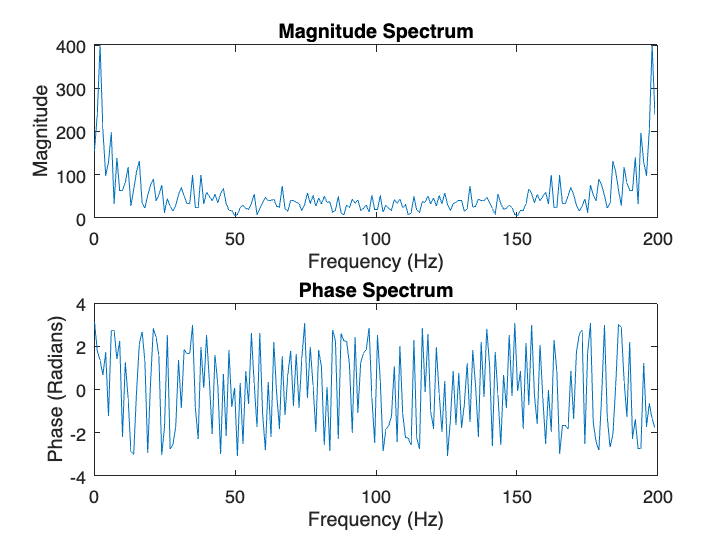

% test recursive FFT in C++ with matlab function
chan1 = Finger1(1,:,1);
F_mat = fft(chan1);

% Compute the length of the signal
N = length(chan1);

% Define the frequency domain
Fs = 200;
f = (0:N-1)*(Fs/N); % replace Fs with the sampling frequency of your signal

% Compute the magnitude and phase of the Fourier Transform
magnitude = abs(F_mat);
phase = angle(F_mat);

% Plot the magnitude spectrum
figure;
subplot(2,1,1);
plot(f, magnitude);
title('Magnitude Spectrum');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

% Plot the phase spectrum
subplot(2,1,2);
plot(f, phase);
title('Phase Spectrum');
xlabel('Frequency (Hz)');
ylabel('Phase (Radians)');

load("fft_results.txt")

Error using load
Unknown text on line number 1 of ASCII file fft_results.txt
"Channel".